% Read Data from Excel
rawTable = readtable('Spacecraft_spin_module_frequency_response_data.xlsx','Sheet','Sheet1');

freq_data = rawTable.Frequency_Hz_;
freq_data = freq_data*2*pi;
mag_data = rawTable.Magnitude__rad_sec__V_;
mag_data = 20*log10(mag_data);
phase_data = rawTable.Phase_rad_ - pi/3;
phase_data = rad2deg(phase_data);

% Curve Fitting Transfer function
% Defining Variables
s = tf('s');
wn1 = 4.6011;
mag1 = 28.1601;
zeta1 = (10^(-mag1/20))/2;
wn2 = 8.28403;
mag2 = 28.9565;
zeta2 = (10^(-mag2/20))/2;

mag_adj = 10^(-1/20);
pole_1 = 0;
pole_2 = 5;
H_adj = 1;
H_res = (s^2 + 2*zeta1*wn1*s + wn1^2) / (s^2 + 2*zeta2*wn2*s + wn2^2);

H = (mag_adj * H_res * H_adj)/((s + pole_1) * (s + pole_2) )

H =
 
     0.8913 s^2 + 0.1603 s + 18.87
  ------------------------------------
  s^4 + 5.295 s^3 + 70.1 s^2 + 343.1 s
 
Continuous-time transfer function.
Model Properties


[mag, phase, freq] = bode(H);

[A, B, C, D] = tf2ss(H.numerator{1}, H.denominator{1})

A =    -5.2954  -70.1022 -343.1258         0
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0


B =      1
     0
     0
     0


C =          0    0.8913    0.1603   18.8679


D = 0

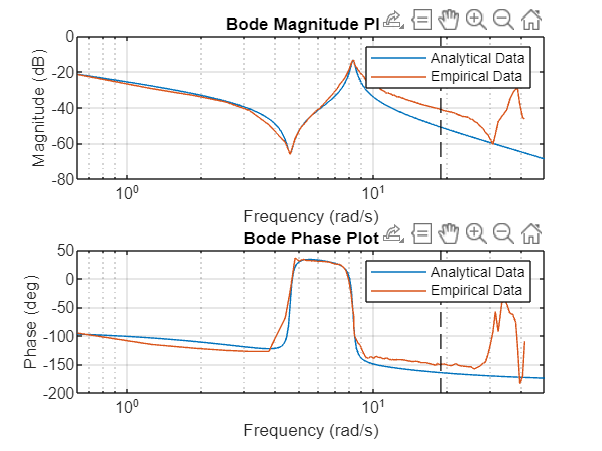


% Generating Bode Plot and comparing Empirical & Analytical Data
figure;
subplot(2,1,1);
semilogx(freq, 20*log10(squeeze(mag)));
xlabel('Frequency (rad/s)');
ylabel('Magnitude (dB)');
title('Bode Magnitude Plot');
grid on;
hold on;
plot(freq_data,mag_data);
xline(3*2*pi, '--k', 'LineWidth', 1);
legend('Analytical Data', 'Empirical Data');
xlim([0.63 50]);
hold off

subplot(2,1,2);
semilogx(freq, squeeze(phase));
xlabel('Frequency (rad/s)');
ylabel('Phase (deg)');
title('Bode Phase Plot');
grid on;
hold on;
plot(freq_data,phase_data);
xline(3*2*pi, '--k', 'LineWidth', 1);
legend('Analytical Data', 'Empirical Data');
axis([0.63 50 -200 50]);